# LAB 3 

## 1)

### A)

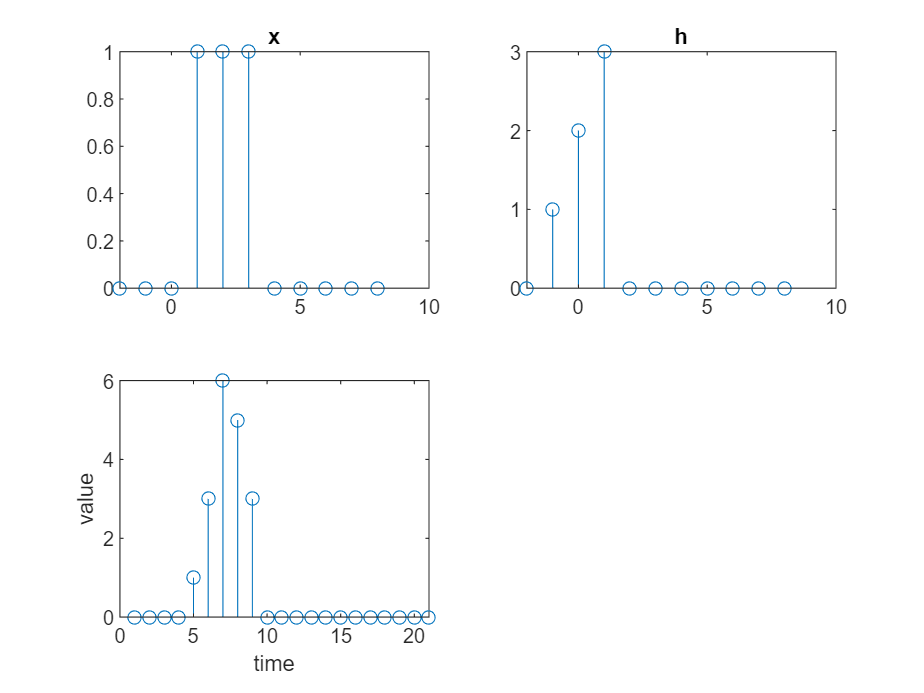


x=ones(1,11);
x(7:end)=0;
x(1,1:3)=0;
t=-2:1:8;
y=zeros(1,11);
y(1,2)=1;y(1,3)=2;y(1,4)=3;
figure(1)
subplot(2,2,1)
stem(t,x)
title('x');
subplot(2,2,2)
stem(t,y)
title('h');
z=conv(x,y);
subplot(2,2,3);
stem(z);
xlabel('time');
ylabel('value');

## B)

anime(x,y,[0:10],[0:10],1);

             BaseValue: {}
            BusyAction: {'queue'  'cancel'}
         ButtonDownFcn: {}
              Children: {}
              Clipping: {[on]  [off]}
                 Color: {1×0 cell}
             ColorMode: {'auto'  'manual'}
           ContextMenu: {}
             CreateFcn: {}
             DeleteFcn: {}
           DisplayName: {}
      HandleVisibility: {'on'  'callback'  'off'}
               HitTest: {[on]  [off]}
         Interruptible: {[on]  [off]}
             LineStyle: {'-'  '--'  ':'  '-.'  'none'}
         LineStyleMode: {'auto'  'manual'}
             LineWidth: {}
                Marker: {1×16 cell}
       MarkerEdgeColor: {'auto'  'none'}
       MarkerFaceColor: {'auto'  'none'}
            MarkerMode: {'auto'  'manual'}
            MarkerSize: {}
                Parent: {}
         PickableParts: {'visible'  'none'  'all'}
              Selected: {[on]  [off]}
    SelectionHighlight: {[on]  [off]}
           SeriesIndex: {}
          ShowBaseLine: {[on]  

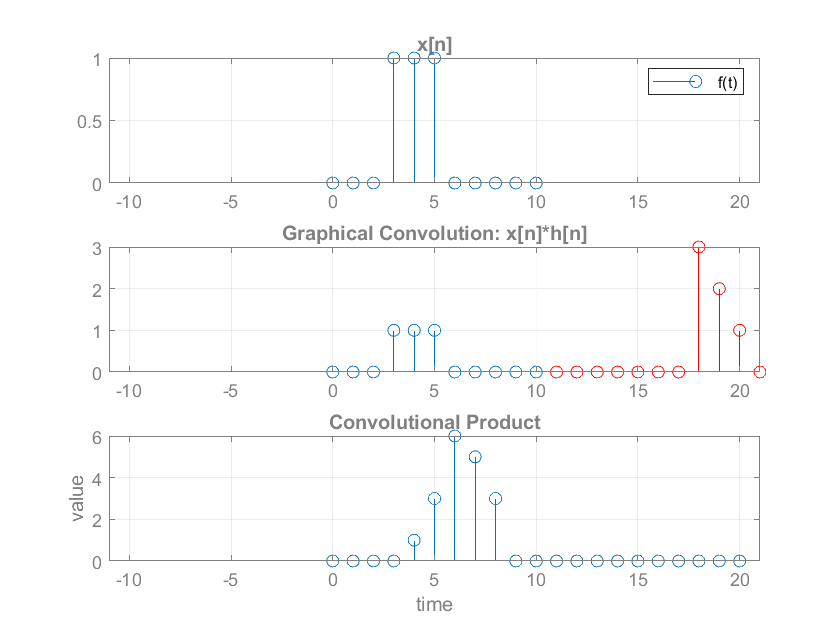

xlabel('time');
ylabel('value');

## C)


c=flip(x)'*flip(y);
[m,n]=size(c);
z=zeros(m,m+n-1);
for i=1:m
for j=1:m
z(i,j+i-1)=c(i,j);
end
end
for i=1:outlen(x,y)
z(1,i)=sum(z(:,i));
end
z=flip(z(1,:));
disp(z);

  Columns 1 through 14

     0     0     0     0     1     3     6     5     3     0     0     0     0     0

  Columns 15 through 21

     0     0     0     0     0     0     0



disp(conv(x,y));

  Columns 1 through 14

     0     0     0     0     1     3     6     5     3     0     0     0     0     0

  Columns 15 through 21

     0     0     0     0     0     0     0



## Task 2)

## A)

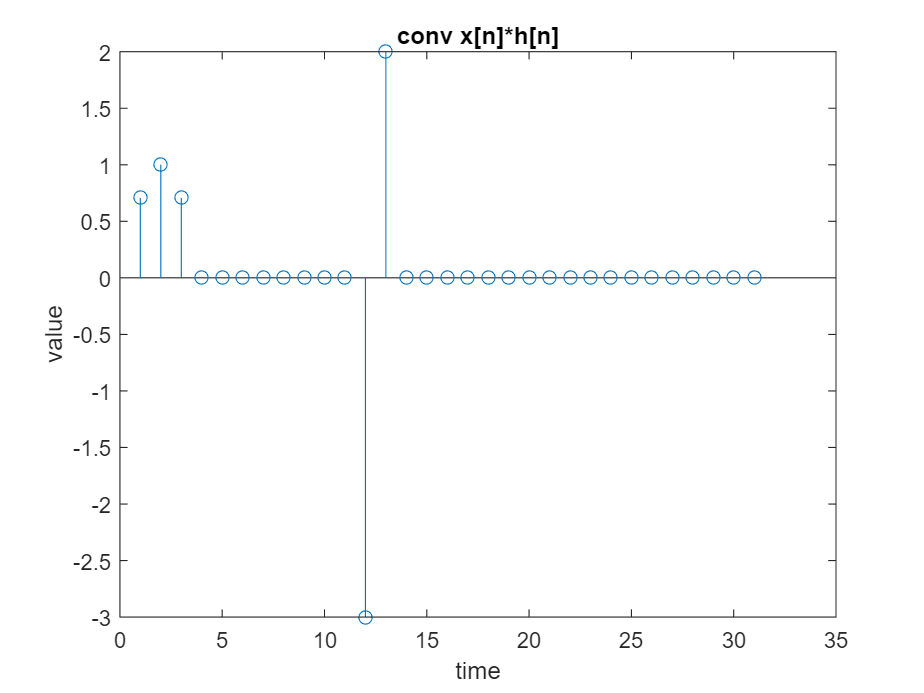


c=0:10;
for n=1:length(c)
    if (c(n)>=0)
        u(n)=1;
    else 
        u(n)=0;
    end
end
for n=1:length(c)
    if (n<=4)
        h(n)=sin(2*pi*n/8)*(u(n));
    else
        h(n)=sin(2*pi*n/8)*(u(n)-u(n-4));
    end
end
x=zeros(size(c));
x(1)=1;

a1=conv(x,h);

figure(3);
stem(a1);
title('conv x[n]*h[n]');
xlabel('time');
ylabel('value');

## B)

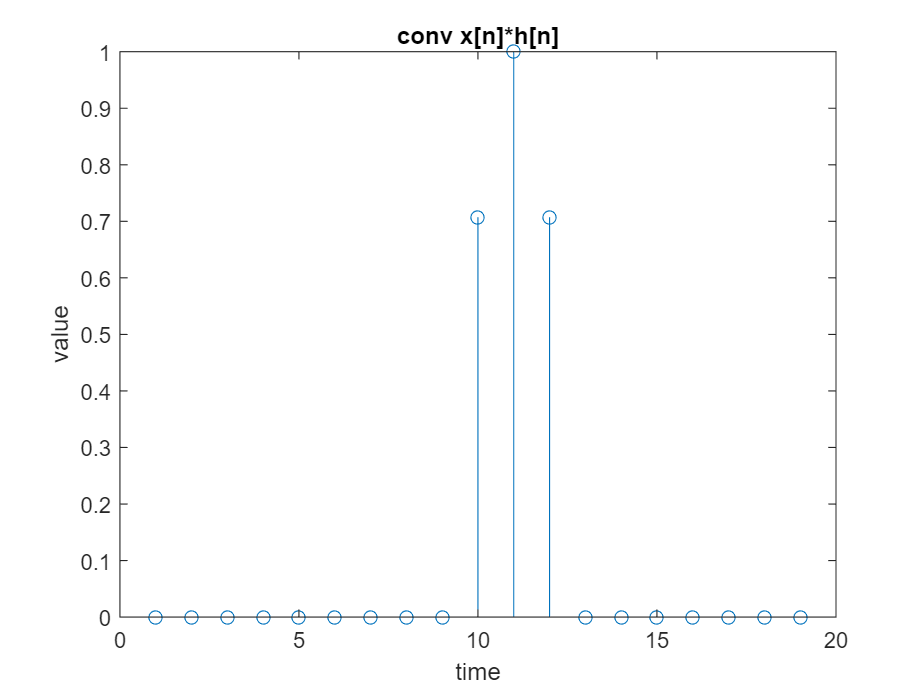

clear h;
c=1:10;
for n=1:length(c)
    if (c(n)>=0)
        u(n)=1;
    else 
        u(n)=0;
    end
end
for n=1:length(c)
    if (n<=4)
        h(n)=sin(2*pi*n/8)*(u(n));
    else
        h(n)=sin(2*pi*n/8)*(u(n)-u(n-4));
    end
end
x=zeros(size(n));


x(10)=1;
a2=conv(x,h);

stem(a2);
title('conv x[n]*h[n]');
xlabel('time');
ylabel('value');

## C)

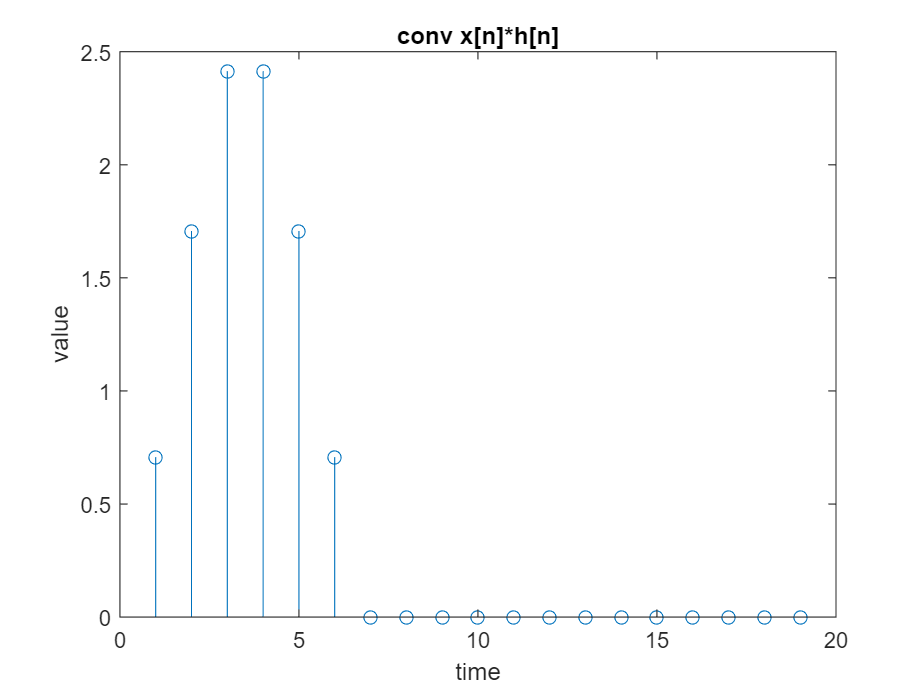

c=1:10;
x=zeros(size(n));

for n=1:length(c)
    if (c(n)>=0)
        u(n)=1;
    else 
        u(n)=0;
    end
end
for n=1:length(c)
    if (n<=4)
        h(n)=sin(2*pi*n/8)*(u(n));
    else
        h(n)=sin(2*pi*n/8)*(u(n)-u(n-4));
    end
end
for n=1:length(c)
    if (n>4)
        x(n)=u(n)-u(n-4);
    else 
        x(n)=u(n);
    end
end


a3=conv(x,h);

stem(a3);
title('conv x[n]*h[n]');
xlabel('time');
ylabel('value');

## D)

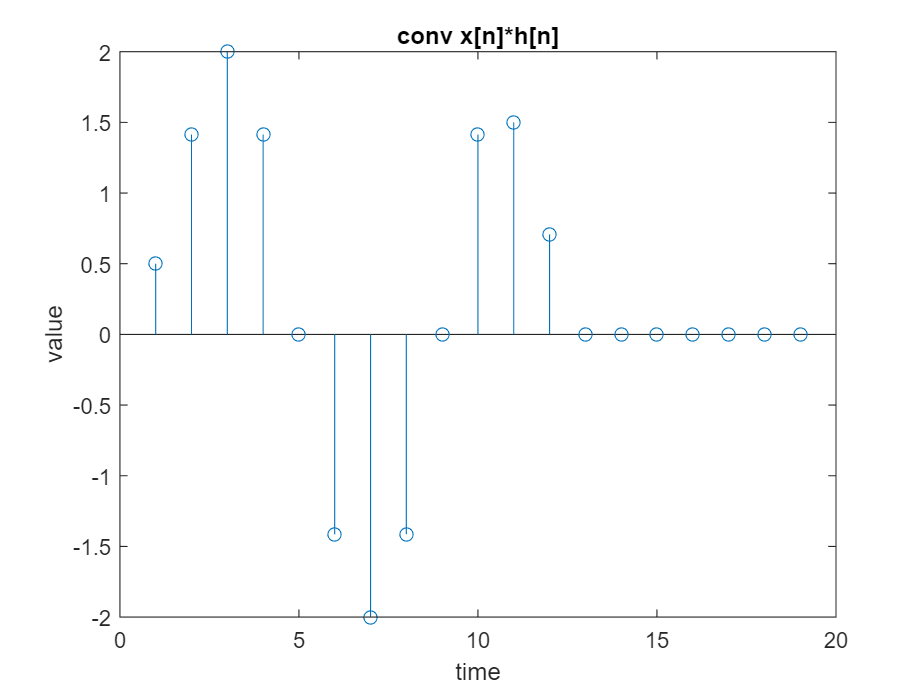

for n=1:length(c)
    if (c(n)>=0)
        u(n)=1;
    else 
        u(n)=0;
    end
end
for n=1:length(c)
    if (n<=4)
        h(n)=sin(2*pi*n/8)*(u(n));
    else
        h(n)=sin(2*pi*n/8)*(u(n)-u(n-4));
    end
end
x=sin(2*pi*c/8);

a4=conv(x,h);

stem(a4);
title('conv x[n]*h[n]');
xlabel('time');
ylabel('value');

## Task 3

## A)

y[n] satisfies the superposition principle therefore it is linear

y[n] is not a function of time so it is time invariant

y[n] does not depend on future values so it is casual

## B)

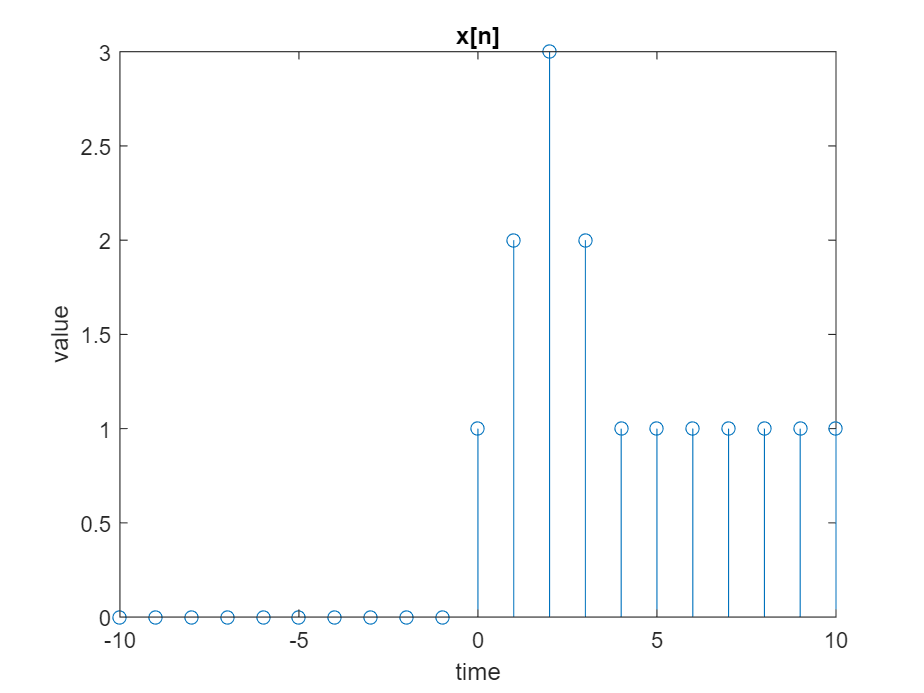

clear;
c=-10:10;
for n=1:length(c)
    if c(n)<0
        x(n)=0;
    else 
        if c(n)>=0 && c(n)<=2
            x(n)=c(n)+1;
       
        else 
            if c(n)>=3 && c(n)<=4
                x(n)=5-c(n);
            else
                if c(n)>=5
                    x(n)=1;
                end
            end
        end
    end
end

stem(c,x)
title('x[n]');
xlabel('time');
ylabel('value');

## C)

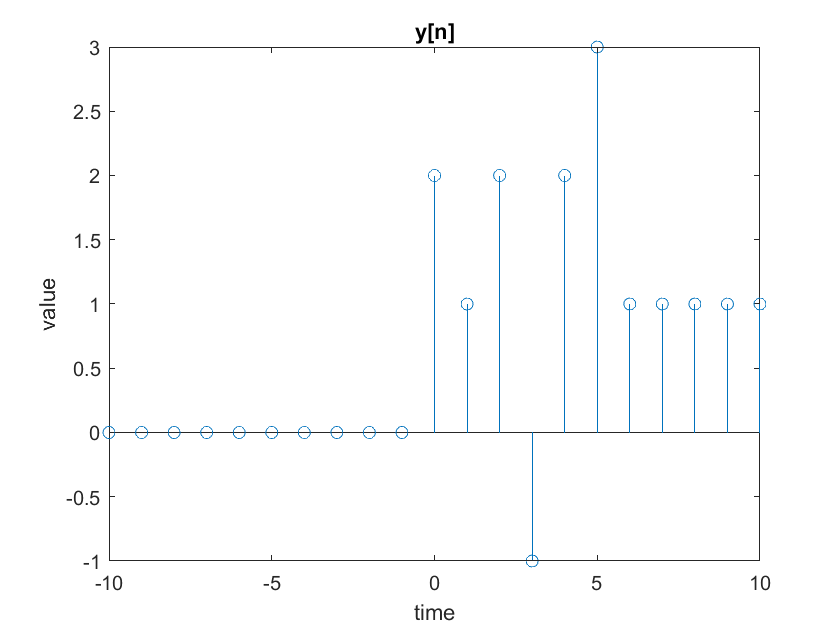

for n=11:1:21
    y(n)=(2*x(n)-3*x(n-1))+2*x(n-2);
end


stem(c,y);
title('y[n]');
xlabel('time');
ylabel('value');

## D)

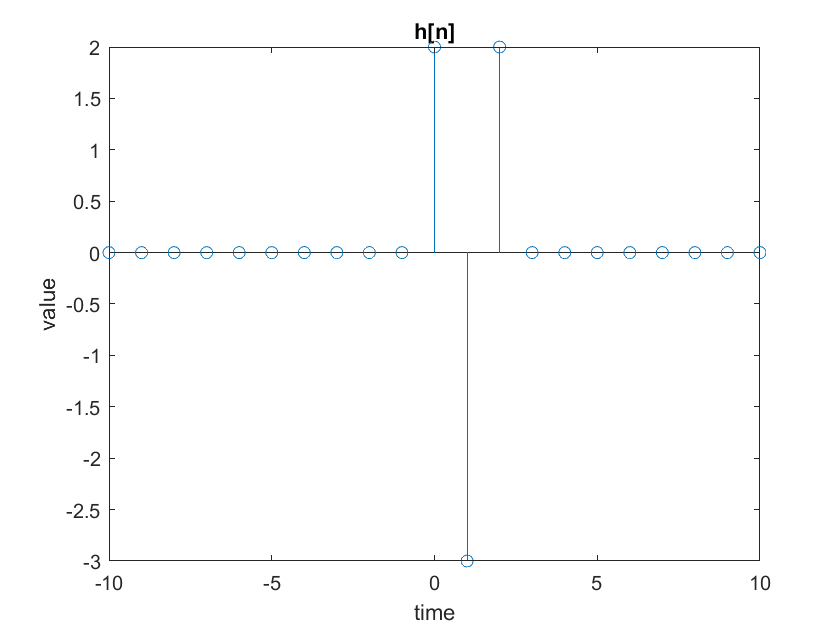

x=zeros(1,length(c));
x(11)=1;
for n=11:1:21
    h(n)=(2*x(n)-3*x(n-1))+2*x(n-2);
end

stem(c,h);
title('h[n]');
xlabel('time');
ylabel('value');

## E)

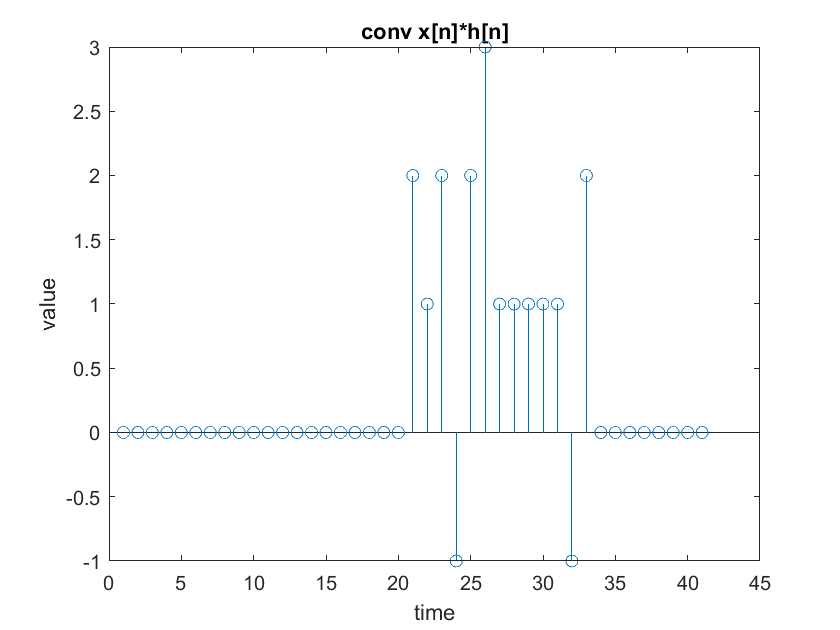

figure(9)
for n=11:1:21
    h(n)=(2*x(n)-3*x(n-1))+2*x(n-2);
end
for n=11:1:21
    if c(n)<0
        x(n)=0;
    else 
        if c(n)>=0 && c(n)<=2
            x(n)=c(n)+1;
       
        else 
            if c(n)>=3 && c(n)<=4
                x(n)=5-c(n);
            else
                if c(n)>=5
                    x(n)=1;
                end
            end
        end
    end
end
stem(conv(x,h));
title('conv x[n]*h[n]')
xlabel('time');
ylabel('value');